# **UNIVERSITAT DE BARCELONA**

# **COMPUTER VISION **

# **LAB 11 REPORT**

**JORGE ALEXANDER & EMER RODRIGUEZ FORMISANO**

VLFeat configuration:

VLFEAT_DIR = 'VLFEATROOT';
run(fullfile(VLFEAT_DIR,'/toolbox/vl_setup'));
vl_version;

0.9.20


a) 

First, train the model with a subset of categories:

vl_phow: color space: gray
vl_phow: image size: 261 x 151
vl_phow: sizes: [ 7]
vl_dsift: image size         [W, H] = [261, 151]
vl_dsift: bounds:            [minX,minY,maxX,maxY] = [1, 1, 261, 151]
vl_dsift: subsampling steps: stepX=5, stepY=5
vl_dsift: num bins:          [numBinT, numBinX, numBinY] = [8, 4, 4]
vl_dsift: descriptor size:   128
vl_dsift: bin sizes:         [binSizeX, binSizeY] = [7, 7]
vl_dsift: flat window:       yes
vl_dsift: window size:       1.5
vl_dsift: num of features:   1248
vl_phow: color space: gray
vl_phow: image size: 261 x 165
vl_phow: sizes: [ 7]
vl_dsift: image size         [W, H] = [261, 165]
vl_dsift: bounds:            [minX,minY,maxX,maxY] = [1, 1, 261, 165]
vl_dsift: subsampling steps: stepX=5, stepY=5
vl_dsift: num bins:          [numBinT, numBinX, numBinY] = [8, 4, 4]
vl_dsift: descriptor size:   128
vl_dsift: bin sizes:         [binSizeX, binSizeY] = [7, 7]
vl_dsift: flat window:       yes
vl_dsift: window size:       1.5
vl_dsift: num of feature

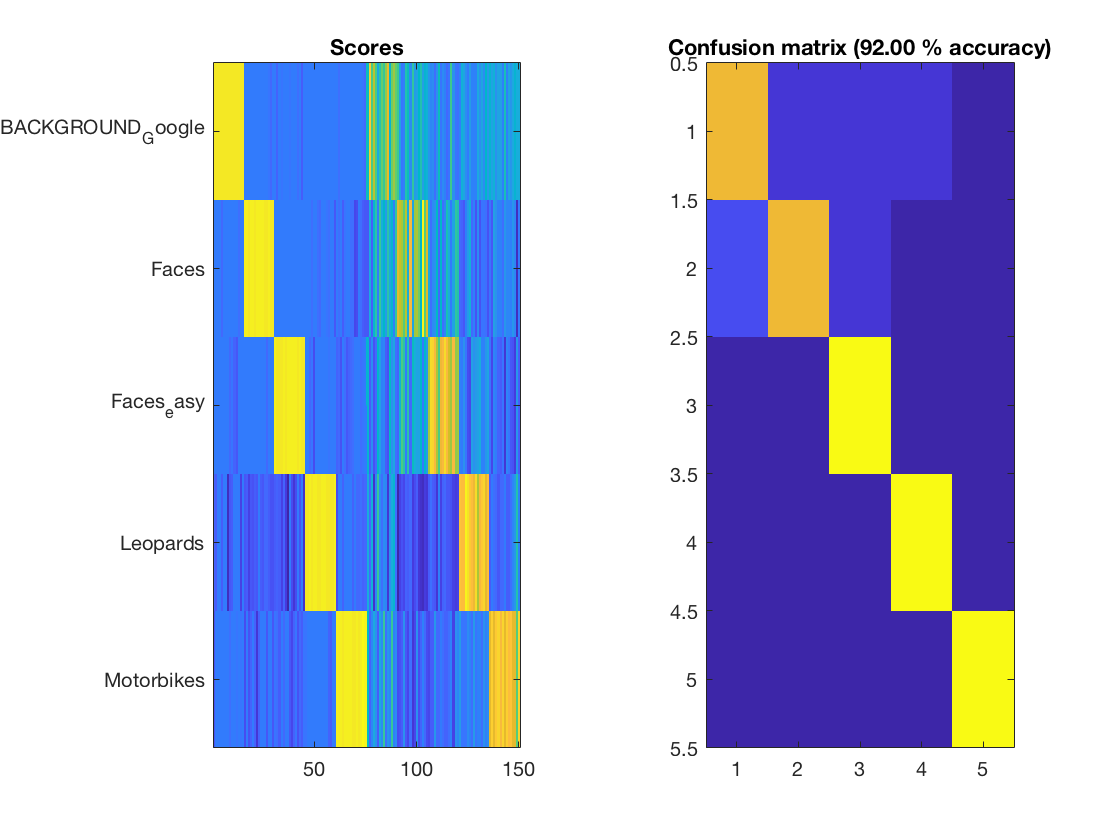

run('modified_phow_caltech101.m');

Add a function to train visualize the images in a green framework if the classification is correct and in a red framework if it does not:

data/caltech-101/101_ObjectCategories/Leopards/image_0040.jpg
data/caltech-101/101_ObjectCategories/Leopards/image_0040.jpg
vl_phow: color space: gray
vl_phow: image size: 192 x 128
vl_phow: sizes: [ 7]
vl_dsift: image size         [W, H] = [192, 128]
vl_dsift: bounds:            [minX,minY,maxX,maxY] = [1, 1, 192, 128]
vl_dsift: subsampling steps: stepX=5, stepY=5
vl_dsift: num bins:          [numBinT, numBinX, numBinY] = [8, 4, 4]
vl_dsift: descriptor size:   128
vl_dsift: bin sizes:         [binSizeX, binSizeY] = [7, 7]
vl_dsift: flat window:       yes
vl_dsift: window size:       1.5
vl_dsift: num of features:   770
data/caltech-101/101_ObjectCategories/Leopards/image_0041.jpg
data/caltech-101/101_ObjectCategories/Leopards/image_0041.jpg
vl_phow: color space: gray
vl_phow: image size: 192 x 128
vl_phow: sizes: [ 7]
vl_dsift: image size         [W, H] = [192, 128]
vl_dsift: bounds:            [minX,minY,maxX,maxY] = [1, 1, 192, 128]
vl_dsift: subsampling steps: stepX=5, stepY=5
vl_d

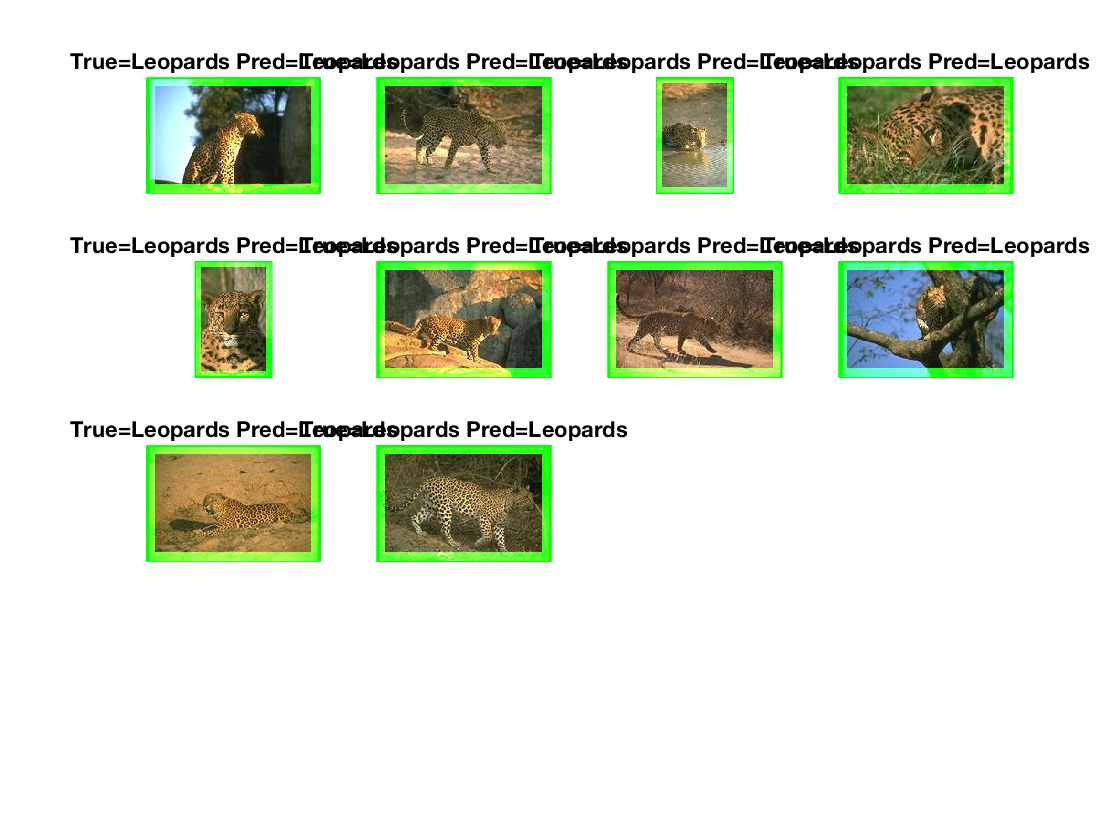

modelPath = 'data/baseline-model.mat';
imageDir = 'data/caltech-101/101_ObjectCategories/Leopards/';
imageNames = dir(fullfile(imageDir, '*.jpg'));
imagePaths = {};
imgPathIdx=1;
for imIdx=40:49    
    imagePaths{imgPathIdx} = fullfile(imageDir, imageNames(imIdx).name);
    imgPathIdx = imgPathIdx + 1;
end
visualizeImgClass(imagePaths, modelPath);

b) 

*What are the PHOW descriptors?  *

They represent the Pyramid Histogram Of visual Words. 

The function to obtain them is 

%[FRAMES, DESCRS] = vl_phow(IMG)

DESCRS, Each column of DESCRS is the descriptor of the corresponding frame in FRAMES. A descriptor is a 128-dimensional vector of class UINT8.

It represents a 4x4 spatial histogram of gradient orientations, each with 8 different directions, leading to a 4x4x8=128 dimensional vector.

FRAMES(1:2,:) are the x,y coordinates of the center of each descriptor, FRAMES(3,:) is the contrast of the descriptor, as returned by VL_DSIFT() (for colour variant, contranst is computed on the intensity channel). FRAMES(4,:) is the size of the bin of the descriptor.

*What does the Sizes parameter mean? *

It's the scales at which the dense SIFT features are extracted. Each value is used as the spatial bin size in pixels when extracting a dense set of SIFT features from the image.

*What does happen if the Sizes parameter is augmented? *

From the lectures, the code to calculate the phow descriptors:

% step = 5;
% for size=[5,7,10,12]
%     [x,y]=meshgrid(1:step:width, 1:step:height);
%     frames = [x(:)'; y(:)'];
%     frames(3,:) = size/3;
%     frames(4,:) = 0;
%     [frames, descrs] = vl_sift(im, 'Frames', frames);
% end

It can be observed that if the size is increased the size of the bin of the descriptor is increased.				

*What does the Step parameter mean?* 

Step (in pixels) of the grid at which the dense SIFT features are extracted.

*What does happen if the Step parameter is augmented?*